# Example: COVID-2019 data for Hubei, China (22-Jan-2020 - )

I am taking some data, collected into DATA.mat from John Hopkins university [1]

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

**Important notice:**

The fitting is here more challenging than in Example 1 because the term "Confirmed patient" used in the database does not precise whether they have been quarantined or not. In a previous version of the submision (version <1.5) , the infectious cases were erroneously used instead of the quarantined cases. 

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();

fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 22-Mar-2020



try
    indLocation = find(contains(tableRecovered.ProvinceState,'Hubei')==1)
catch exception
    searchLoc = strfind(tableRecovered.ProvinceState,'Hubei')
    indLocation = find([searchLoc{:}]==1)
end

indLocation = 156





Recovered = table2array(tableRecovered(indLocation,5:end));
Deaths = table2array(tableDeaths(indLocation,5:end));
Confirmed = table2array(tableConfirmed(indLocation,5:end));
% If the number of confirmed Confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
minNum= 50;
Recovered(Confirmed<=minNum)=[];
Deaths(Confirmed<=minNum)=[];
time(Confirmed<=minNum)= [];
Confirmed(Confirmed<=minNum)=[];

% time = datetime(2020,02,24):1:datetime(2020,03,17);

Npop= 14e6; % population

## Fitting of the generalized SEIR model to the real data

% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 1.0; % Infection rate
LT_guess = 5; % latent time in days
QT_guess = 21; % quarantine time in days
lambda_guess = [0.1,0.05]; % recovery rate
kappa_guess = [0.1,0.05]; % death rate

guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    1/QT_guess,...
    lambda_guess,...
    kappa_guess];


% Initial conditions
E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Confirmed(1);
R0 = Recovered(1);
D0 = Deaths(1);

% Parameter estimation with the lsqcurvefit function
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Confirmed-Recovered-Deaths,Recovered,Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9     2.84413e+11                      4.59e+13
     1         18     2.80416e+10      0.0684634       2.56e+12      
     2         27     2.80416e+10      0.0622327       2.56e+12      
     3         36     2.09619e+10      0.0155582       1.03e+11      
     4         45      1.7346e+10      0.0311164       1.45e+11      
     5         54     1.31444e+10      0.0622327       7.25e+10      
     6         63     8.27288e+09       0.124465       6.74e+10      
     7         72     8.27288e+09      0.0885274       6.74e+10      
     8         81     7.11034e+09      0.0221319       3.58e+10      
     9         90     5.77223e+09      0.0442637       3.98e+11      
    10         99     3.57284e+09      0.0885274       3.63e+10      
    11        108     3.57284e+09       0.164217       3.63e+10      
    12        117     3.09092e+0

## Simulate the epidemy outbreak based on the fitted parameters

dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(2020,3,25,0,0,0);
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

## Comparison of the fitted and real data

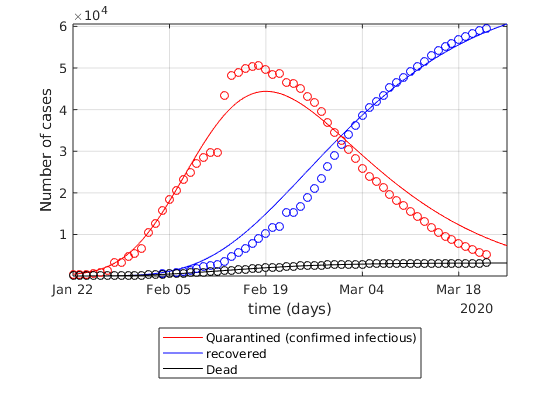

figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Confirmed-Recovered-Deaths,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
% leg = {'susceptible','exposed','infectious','quarantined','recovered','Dead','insusceptible'};
leg = {'Quarantined (confirmed infectious)','recovered','Dead'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
% ylim([1,8e4])
set(gca,'yscale','lin')